## Estabilidad de sistemas no lineales mediante el método indirecto de Lyapunov

Consideremos como ejemplo básico el péndulo invertido

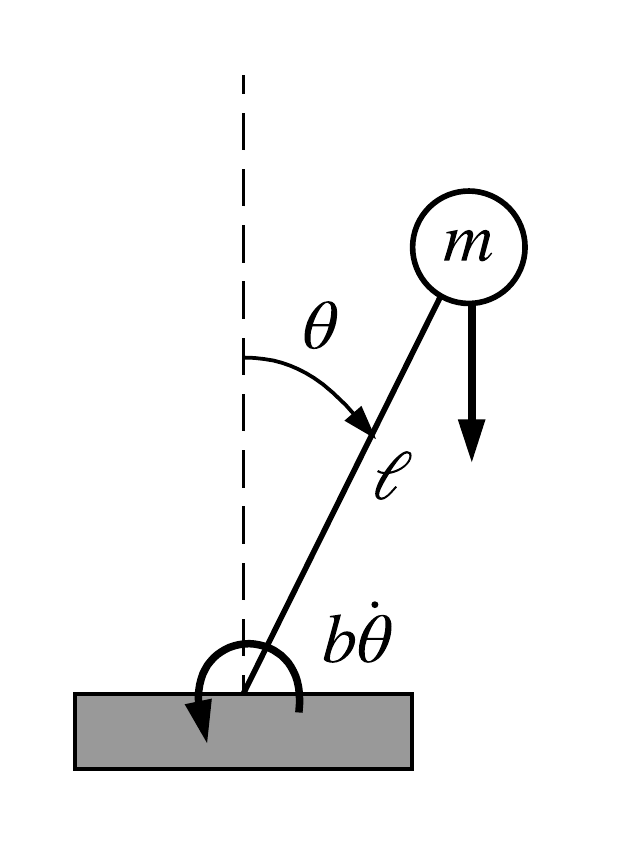

y tratemos de encontrar la estabilidad (local) de los puntos de equilibrio: verticalmente hacia arriba:

xeq1 = [0; 0];
ueq1 = 0;

y verticalmente hacia abajo:

%xeq2 = [pi; 0];
xeq2 = [0; 0];
ueq2 = 0;

Para lograr esto emplearemos el método indirecto de Lyapunov, para el cual requerimos las linealizaciones alrededor de los puntos de interés. Si bien sabemos que es posible emplear la Toolbox de matemática simbólica de MATLAB para calcular los jacobianos, obviemos este paso y acudamos directamente a los métodos numéricos. Primero definimos el campo vectorial del sistema:

g = 9.8; % m/s^2
m = 1; % kg
ell = 1; % m
b = 0.5;

%dynamics = @(x, u) [x(2); (g/ell)*sin(x(1)) - (b/(m*ell^2))*x(2)];
%dynamics = @(x, u) [-x(1)+x(1)*(x(1)^2 + x(2)^2); -x(2)+x(2)*(x(1)^2 + x(2)^2)];
dynamics = @(x,u) [x(2); -x(1)-x(2)];
outputs = @(x,u) x; % dummy para poder emplear loclin

Luego, calculamos la linealización local alrededor del primer punto de equilibrio y encontramos sus eigenvalores:

% En este caso podemos "tirar" todas las matrices que no sean A ya que 
% sólo necesitamos esta para la conclusión sobre estabilidad
[A1, ~, ~, ~] = loclin_best(dynamics, outputs, xeq1, ueq1);

% Encontramos los eigenvalores (polos) de A
eig(A1)

ans =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i


De donde podemos ver que la linealización es inestable y, por lo tanto, **el primer punto de equilibrio del sistema no lineal es (localmente) inestable**.

Finalmente, repetimos el proceso para el segundo punto de equilibrio:

[A2, ~, ~, ~] = loclin_best(dynamics, outputs, xeq2, ueq2);
eig(A2)

ans =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i


De donde concluimos que la linealización es G.A.S. y, por lo tanto, **el segundo punto de equilibrio del sistema no lineal es (localmente) asintóticamente estable**.

El mismo proceso puede repetirse para sistemas más complicados, siempre y cuando tengamos una manera de encontrar sus puntos de equilibrio y/u operación.